% HW#7 Prob 3 (1) Watt II mechanism configuration

% Watt II mechanism
clc;clear;close all
% parameters
d2r=pi/180;
r2d=180/pi;
%link parameters for four bar 1
W1 = 1; th = 90*d2r; 
V1 = 1.5; rho = 19.3737*d2r; 
U1 = 1.5; sigma = 93.2461*d2r; 
G1x=1.5;G1y=0;
L1=1; delta=60.7834*d2r;
W1_s=1; th_s=45*d2r; 
V1_s=1.5; rho_s=7.9416*d2r;
U1_s=1.5; sigma_s=60.2717*d2r;
G1x_s=1.4489;G1y_s=-0.3882;
L1_s=1; delta_s=49.3512*d2r;
%
% initial configuration plot with dashed lines
Wx=W1*cos(th); Wy=W1*sin(th);
Vx=V1*cos(rho); Vy=V1*sin(rho);
Ux=U1*cos(sigma); Uy=U1*sin(sigma);
Lx=L1*cos(delta); Ly=L1*sin(delta);
Wx_s=W1_s*cos(th_s); Wy_s=W1_s*sin(th_s)

Wy_s = 0.7071

Vx_s=V1_s*cos(rho_s); Vy_s=V1_s*sin(rho_s);
Ux_s=U1_s*cos(sigma_s); Uy_s=U1_s*sin(sigma_s);
Lx_s=L1_s*cos(delta_s); Ly_s=L1_s*sin(delta_s);
fourbarLx=[0 Wx Wx+Lx Wx+Vx Wx Wx+Vx G1x];
fourbarLy=[0 Wy Wy+Ly Wy+Vy Wy Wy+Vy G1y];
middlex=[G1x G1x+Ux G1x+Wx_s G1x];
middley=[G1y G1y+Uy G1y+Wy_s G1y];
fourbarRx=[G1x G1x+Wx_s G1x+Wx_s+Lx_s G1x+Wx_s+Vx_s G1x+Wx_s G1x+Wx_s+Vx_s G1x+G1x_s];
fourbarRy=[G1y G1y+Wy_s G1y+Wy_s+Ly_s G1y+Wy_s+Vy_s G1y+Wy_s G1y+Wy_s+Vy_s G1y+G1y_s];
plot(fourbarLx,fourbarLy,'--ko');
hold on
plot(fourbarRx,fourbarRy,'--ko');
plot(middlex,middley,'--ko');
axis ([-1 4 -2 3])
grid on
% beta=-270 deg
beta=-270*d2r;
% initial alpha and gama for left 4 bar mechanism
x0=[0 0];
% define fx position loop equation x=[beta alpha] [1st 4 bar]
fx=@(x)[W1*cos(th+beta)+V1*cos(rho+x(1))-U1*cos(sigma+x(2))-G1x;...
        W1*sin(th+beta)+V1*sin(rho+x(1))-U1*sin(sigma+x(2))-G1y];
x=fsolve(fx,x0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



%
alpha=x(1); gama=x(2);
% initial alpha_s and gama_s for right 4 bar
x0_s=[0 0];  
beta_s=gama; % left follower angle becomes crank angle of right 4 bar
% define fx_s position loop equation x_s=[alpha_s gama_s] [2nd 4 bar]
fx_s=@(x_s)[W1_s*cos(th_s+beta_s)+V1_s*cos(rho_s+x_s(1))-U1_s*cos(sigma_s+x_s(2))-G1x_s;...
    W1_s*sin(th_s+beta_s)+V1_s*sin(rho_s+x_s(1))-U1_s*sin(sigma_s+x_s(2))-G1y_s];
x_s=fsolve(fx_s,x0_s);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



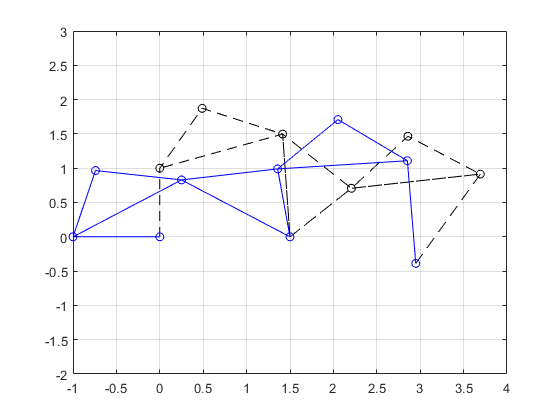

%
alpha_s=x_s(1); gama_s=x_s(2);
% plot of likage for beta=-270 deg
Wx=W1*cos(th+beta); Wy=W1*sin(th+beta);
Vx=V1*cos(rho+alpha); Vy=V1*sin(rho+alpha);
Ux=U1*cos(sigma+gama); Uy=U1*sin(sigma+gama);
Lx=L1*cos(delta+alpha); Ly=L1*sin(delta+alpha);
Wx_s=W1_s*cos(th_s+beta_s); Wy_s=W1_s*sin(th_s+beta_s);
Vx_s=V1_s*cos(rho_s+alpha_s); Vy_s=V1_s*sin(rho_s+alpha_s);
Ux_s=U1_s*cos(sigma_s+gama_s); Uy_s=U1_s*sin(sigma_s+gama_s);
Lx_s=L1_s*cos(delta_s+alpha_s); Ly_s=L1_s*sin(delta_s+alpha_s);
fourbarLx=[0 Wx Wx+Lx Wx+Vx Wx Wx+Vx G1x];
fourbarLy=[0 Wy Wy+Ly Wy+Vy Wy Wy+Vy G1y];
middlex=[G1x G1x+Ux G1x+Wx_s G1x];
middley=[G1y G1y+Uy G1y+Wy_s G1y];
fourbarRx=[G1x G1x+Wx_s G1x+Wx_s+Lx_s G1x+Wx_s+Vx_s G1x+Wx_s G1x+Wx_s+Vx_s G1x+G1x_s];
fourbarRy=[G1y G1y+Wy_s G1y+Wy_s+Ly_s G1y+Wy_s+Vy_s G1y+Wy_s G1y+Wy_s+Vy_s G1y+G1y_s];
plot(fourbarLx,fourbarLy,'-bo');
hold on
plot(fourbarRx,fourbarRy,'-bo');
plot(middlex,middley,'-bo');
axis ([-1 4 -2 3])


% Show Linkage Components
str = ["Wx" "Wy" "Vx" "Vy" "Ux" "Uy" "Wx_s" "Wy_s" "Vx_s" "Vy_s" "Ux_s" "Uy_s"]';
table(str,[Wx Wy Vx Vy Ux Uy Wx_s Wy_s Vx_s Vy_s Ux_s Uy_s]')

ans = 12×2 table
     str         Var2    
    ______    ___________

    "Wx"               -1
    "Wy"      -1.2246e-16
    "Vx"             1.25
    "Vy"          0.82916
    "Ux"            -1.25
    "Uy"          0.82916
    "Wx_s"       -0.14257
    "Wy_s"        0.98978
    "Vx_s"         1.4953
    "Vy_s"        0.11893
    "Ux_s"      -0.096192
    "Uy_s"         1.4969


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Applied Forces
Fp1x = 0;
Fp1y = -1500;
Fp1_sx = -2500;
Fp1_sy = -1000;

% Formulate Ax = b matrixes
    % Coeffecient Matrix (A) eq 6.31
R1 = [0 1 0 1 zeros(1,11)];
R2 = [0 0 1 0 1 zeros(1,10)];
R3 = [1 0 0 -Wy Wx zeros(1,10)];
R4 = [0 0 0 -1 0 0 0 -1 zeros(1,7)];
R5 = [0 0 0 0 -1 0 0 0 -1 zeros(1,6)];
R6 = [zeros(1,7), Vy -Vx zeros(1,6)];
R7 = [zeros(1,5) 1 0 1 0 1 zeros(1,5)];
R8 = [zeros(1,6) 1 0 1 0 1 zeros(1,4)];
R9 = [zeros(1,7) -Uy Ux -Wy_s Wx_s zeros(1,4)];
R10R16 = [zeros(6,9)...
    [-1 zeros(1,5)]'...
    [0 -1 zeros(1,4)]'...
    [0 0 0 1 0 0 ]'...
    [zeros(1,4) 1 0]'...
    [-1 0 Vy_s 1 0 -Uy_s]'...
    [0 -1 -Vx_s 0 1 Ux_s]'];

A = [R1;R2;R3;R4;R5;R6;R7;R8;R9;R10R16]

A =          0    1.0000         0    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0         0    1.0000         0    1.0000         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0    0.0000   -1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0   -1.0000         0         0         0   -1.0000         0         0         0         0         0         0         0
         0         0         0         0   -1.0000         0         0         0   -1.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0    0.8292   -1.2500         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0    1.0000         0




    % Given Matrix (b) eq 6.31
b = [0 0 0 -Fp1x -Fp1y Fp1x*Ly-Fp1y*Lx...
    0 0 0 -Fp1_sx -Fp1_sy Fp1_sx*Ly_s-Fp1_sy*Lx_s 0 0 0]';

    % Unknown Vector (x) eq 6.31
x = A\b;

    % Display Unknown Values in Accordance to eq 6.31
str = ["T_a0" "F_a0x" "F_a0y" "F_a1x" "F_a1y" "F_b0x" "F_b0y" "F_b1x" "F_b1y"...
    "F_a1x_s" "F_a1x_s" "F_b0x_s" "F_b0y_s" "F_b1x_s" "F_b1y_s"]';
table(str,x)

ans = 15×2 table
       str          x   
    _________    _______

    "T_a0"       -2414.3
    "F_a0x"       1847.7
    "F_a0y"       2414.3
    "F_a1x"      -1847.7
    "F_a1y"      -2414.3
    "F_b0x"       605.23
    "F_b0y"        818.8
    "F_b1x"       1847.7
    "F_b1y"       914.34
    "F_a1x_s"    -2452.9
    "F_a1x_s"    -1733.1
    "F_b0x_s"     47.112
    "F_b0y_s"    -733.14
    "F_b1x_s"    -47.112
    "F_b1y_s"     733.14
